clc;clearvars;close all;
global DOFS;
DOFS = [true,true,true];
L1 = sqrt(10^2+80^2);
L2 = sqrt(60^2+80^2);
E = 2e4;
I2 = 184.952;
I1 = 536.917;
A2 = 7.04; A1 = 11;
Aeq2 = 2.3;
Aeq1 = 3.09;
v = 0.3;
p = 20;
n1 = NODES(1,0  ,0,"constraint" ,"fixed",dy=-0.2,dRz=-deg2rad(4));
n2 = NODES(2,0  ,50,"constraint" ,"fixed",fy=-20);
n3 = NODES(3,80,60); n3.dof_inds=[7,8,9,10];n3.Anf=[0,-40,0,0].'; n3.iscons=[1,0,1,0];n3.An=[0,-40,0,0].';n3.D=[0,0,0,0].';

cr1 = tempcross(E,A1,I=I1,Aeq=Aeq1,d=16);
cr2 = tempcross(E,A2,I=I2,Aeq=Aeq2,d=12);
m1 = member(n2,n3,cr1,"alpha",12e-6,"Tu",40,"Tl",-20);m1.mdofs=[4,5,6,7,8,9];
m2 = member(n1,n3,cr2,"alpha",12e-6,"pre",-0.2,"Tu",-20,"Tl",40);m2.mdofs=[1,2,3,7,8,10];

L1i = rec(m1,0,L1,0.1*80/L1,"down","g");

## Automatically creating the cell matrices and running the final solver

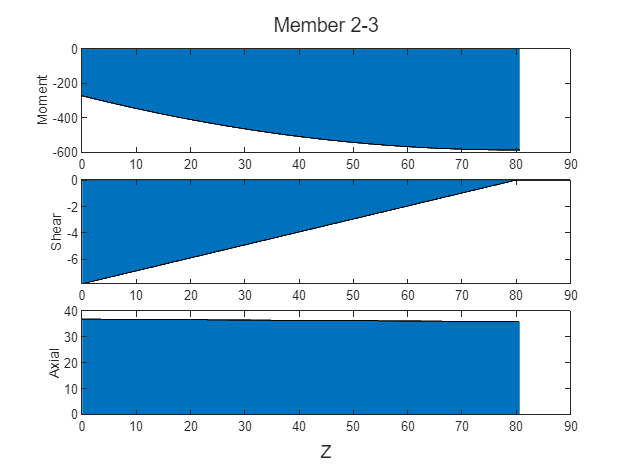

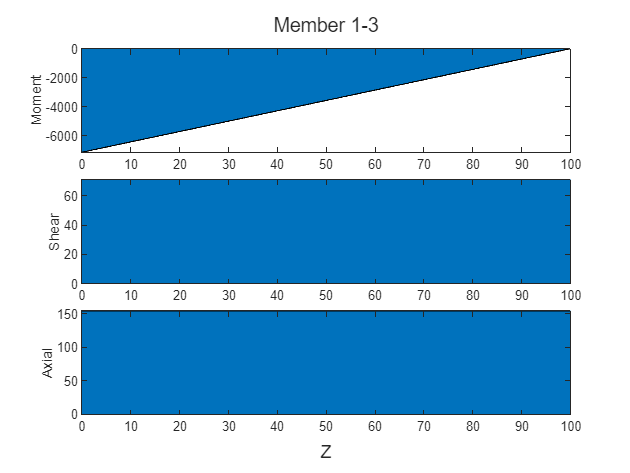

Deflections:
   -0.0293
    0.0324

Reactions:
   1.0e+03 *

    0.1662
    0.0356
   -7.1193
    0.0356
    0.0324
   -0.2727
   -0.2017
    0.5871




members = {};
nodes = {};
loads = {};
j = evalin('base','who');
for n = 1:length(j)
    r = evalin('base',j{n});
    if isa(r,'member')
        members = {members{:},r};
    elseif isa(r,'NODES')
        nodes = {nodes{:},r};
    elseif isa(r,'con_fm')||isa(r,'con_m')||isa(r,'n_tri')||isa(r,'rec')||isa(r,'rev_tri')
        loads = {loads{:},r};
    end
end
[Ar,D,Df,members] = final_solver(members,nodes,loads);